# HOMEWORK 3

Author ~ Ahmed Magd Aly

Innopolis University

## Question 1:

### Derive the forward kinematics for the robot:

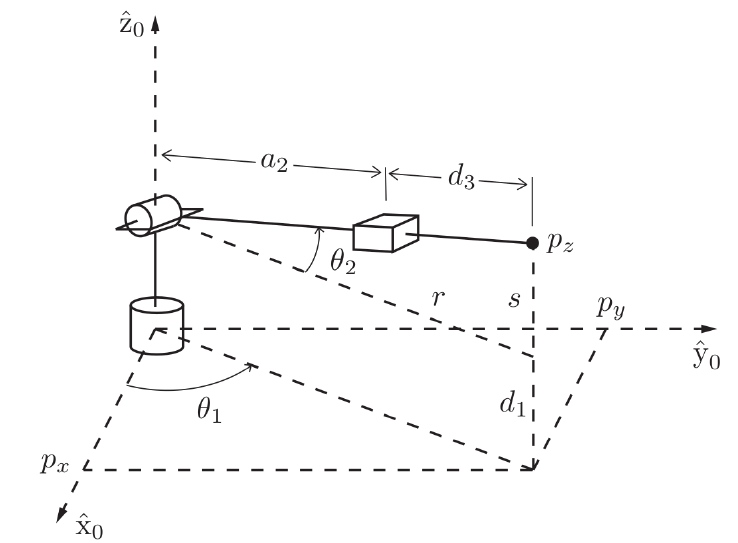

clear all
close all
clc
syms theta1 theta2 d1 a2 d3
fk = Rz(theta1)*Tz(d1)*Ry(-theta2)*Tx(a2)*Tx(d3);
simplify(fk);


In following solutions, it assumed that d1 and a2 are 175 and 500 respectively

Let's visualize the robot

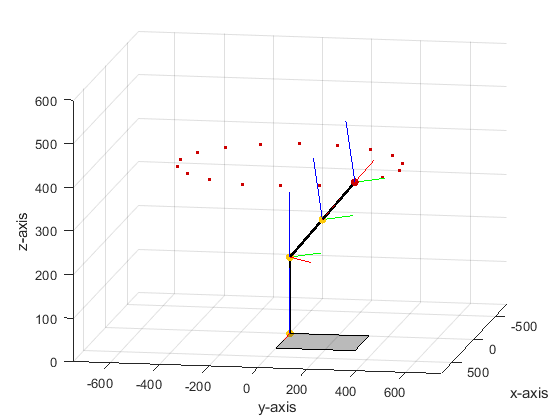

figure
title("Forward Kinematics")
global axes_plot links_plot joints_plot end_effector_plot plane_plot
for i=45:20:405
    delete([links_plot,joints_plot,end_effector_plot,plane_plot]), delete(axes_plot)
    % FK(theta1, theta2, d3, turn_plot_on)
    FK(i,25,250,1);
    
    xlim([-750 750])
    ylim([-750 750])
    view([100 15])
    drawnow
end

### Question 2:

### Derive the inverse kinematics of the robot (all possible solutions):

from the geometry we can compute the IK solutions, and also from the geometry, we know that there are 4 possible solutions. Two solutions are physically possible, while the other two are not possible because they use negative values for d3. However, these solutions exists and they might be applied in some unusal robots design.

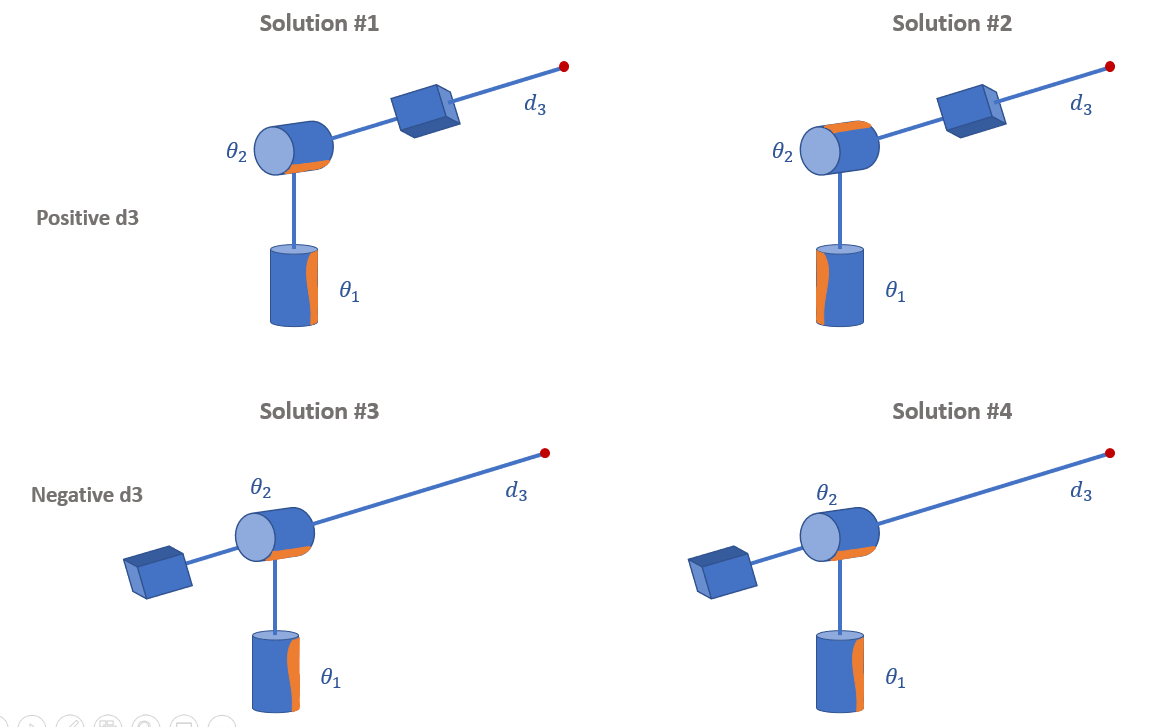

For q1:

syms px py pz
q11 = atan2(py,px);
q12 = atan2(-py,-px);

For q2, It can be computed with atan2, but it will be atan between the projection on the xy-plane and the z plane, thus it will be as follow:


$$\textrm{q2}=\textrm{atan2}\left(\frac{\textrm{pz}-\textrm{d1}}{\sqrt{x^2 +y^2 }}\right)$$


q21 = atan2(pz-d1,sqrt(px^2 + py+2));
q22 = atan2(-pz+d1,-sqrt(px^2 + py+2));

For d3, we can use pythagoras theorem as follow:

d31 = sqrt(px^2 + py^2 + (pz-d1)^2) - a2;
d32 = -sqrt(px^2 + py^2 + (pz-d1)^2) - a2;

So the all the solutions could be written as follow:

q = [q11 q21 d31;
     q12 q22 d31;
     q11 q22 d32;
     q12 q21 d32];

Let's visualize the IK solutions

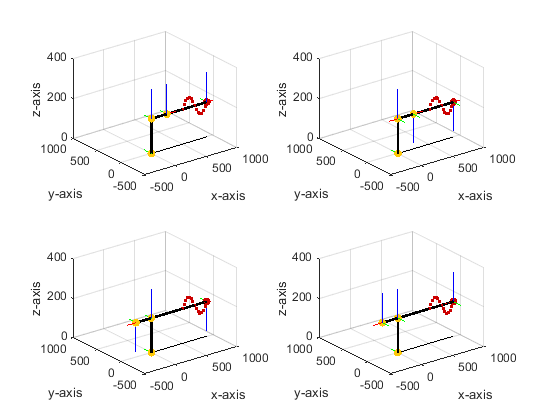

 close all
 for t=linspace(0,2*pi^2,15)
    z=175+50*sin(t/pi);
    y=0;
    x=500+20*t;
    
    q = IK(x,y,z);
    delete([links_plot,joints_plot,end_effector_plot,plane_plot]), delete(axes_plot)
    for i=1:4
        subplot(2,2,i)
        FK(q(i,1),q(i,2),q(i,3),1);
        xlim([-500 1000]), ylim([-500 1000])
    end
    drawnow
 end